## B Running HPC for LDE, then test LIF only

## 1. Setting up network

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(DataFolder)

### B1. Load LDE computations and do Fr distributions

%load("AllMFPixPara_Paper2TuneFig1V4D2.mat")
load("AllMFPixPara_Paper2TuneFig1V4.mat")
%load("AllMFPixPara_Paper2Tune.mat")
close all

if MF+v: omitting

If LIF-only: see coverage. Omitting

## 2. Set up LDE firing rate functions

from HPC LDE computed results

% Determine L4 Input from a range
% Expectation of kick numbers received by 1 neuron in each type
% L4SE = zeros(N_HC*NPixX*N_HC*NPixY,1);
% L4SI = zeros(N_HC*NPixX*N_HC*NPixY,1);
% L4CE = zeros(N_HC*NPixX*N_HC*NPixY,1);
% L4CI = zeros(N_HC*NPixX*N_HC*NPixY,1);
% L4IE = zeros(N_HC*NPixX*N_HC*NPixY,1);
% L4II = zeros(N_HC*NPixX*N_HC*NPixY,1);
% for PInd = 1:N_HC*NPixX*N_HC*NPixY
%     L4SE(PInd) = (C_SS_Pixel_Us(PInd,:)*FrSPixVec          + C_SC_Pixel_Us(PInd,:)*FrCPixVec)...
%         - C_SS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_SC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
%     L4SI(PInd) =  C_SI_Pixel_Us(PInd,:)*FrIPixVec - C_SI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
%     L4CE(PInd) = (C_CS_Pixel_Us(PInd,:)*FrSPixVec          + C_CC_Pixel_Us(PInd,:)*FrCPixVec)...
%         - C_CS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_CC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
%     L4CI(PInd) =  C_CI_Pixel_Us(PInd,:)*FrIPixVec - C_CI_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
%     L4IE(PInd) = (C_IS_Pixel_Us(PInd,:)*FrSPixVec          + C_IC_Pixel_Us(PInd,:)*FrCPixVec)...
%         - C_IS_Pixel_Us(PInd,PInd)*FrSPixVec(PInd) - C_IC_Pixel_Us(PInd,PInd)*FrCPixVec(PInd);
%     L4II(PInd) =  C_II_Pixel_Us(PInd,:)*FrIPixVec - C_II_Pixel_Us(PInd,PInd)*FrIPixVec(PInd);
% end

Proportions between the distributions of kicks to SCI cells

Assumption here: Total kicks received by the same pixel should be

proportional to SCI

NLDEFunc = 7;
load(['Paper2_LIFoLDE1_Fig1V4D1_Grating.mat'])
%load(['Paper2_LDE1_Fig1V4.mat'])
a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);
rowsmWin = 15; colswWin = 5;
MFv = false;
smth = true;
if MFv 
    LIFN = 5;
else
    LIFN = 3;
end
figure('Name','LDERateFunctions')
CtgrName = {'func1','func2','func3','func4','func5','func6','func7'};
LDEFrVecS = zeros(length(L4ERcrd),NLDEFunc);
LDEFrVecC = zeros(length(L4ERcrd),NLDEFunc);
LDEFrVecI = zeros(length(L4ERcrd),NLDEFunc);
for Ctgr = 1:NLDEFunc
    load(['Paper2_LIFoLDE' num2str(Ctgr) '_Fig1V4D1_Grating.mat'])
    %load(['Paper2_LDE' num2str(Ctgr) '_Fig1V4.mat'])
    L4EPlot = reshape(L4ERcrd,a2,a1);
    L4IPlot = reshape(L4IRcrd,a2,a1);
    FrLDE = zeros(length(f_EnIOut),LIFN);
    for LDEInd = 1:length(f_EnIOut)
        if ~(isempty(f_EnIOut{LDEInd}) || size(f_EnIOut{LDEInd},2)<25)
            FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,floor(end/2):end),2))';
        else
            FrLDE(LDEInd,:) = nan;
        end
    end
    FrLDE(FrLDE<0) = eps;
    % S rates
    subplot(NLDEFunc,3,(Ctgr-1)*3+1)
    LDEFrVecS(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
        CtgrName,Ctgr,'S',smth,true,MFv, [rowsmWin, colswWin] );

    % C rates
    subplot(NLDEFunc,3,(Ctgr-1)*3+2)
    LDEFrVecC(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
        CtgrName,Ctgr,'C',smth,true,MFv, [rowsmWin, colswWin] );

    % I rates
    subplot(NLDEFunc,3,(Ctgr-1)*3+3)
    LDEFrVecI(:,Ctgr) = ...
        LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
        CtgrName,Ctgr,'I',smth,true,MFv, [rowsmWin, colswWin] );
end
close all

Create a function

L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400);
L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
[L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);
% 2D function now, depending on input of total E and I kick numbers
for Ctgr = 1:NLDEFunc
LDEFrfunc.S{Ctgr} = griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,Ctgr),L4EmeshX, L4ImeshY);
LDEFrfunc.C{Ctgr} = griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,Ctgr),L4EmeshX, L4ImeshY);
LDEFrfunc.I{Ctgr} = griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,Ctgr),L4EmeshX, L4ImeshY);
end

Test the ranges for L6 and LGN input

figure('Name','All Possible Combs L6 LGN')
LGNL6Pix_All = [];
for Grating = 0:5:90 % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2

FigOn = false;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;

L6smear = n_S_HC/4; LGNsmear = 1;
L6SFilt_Grating = SpatialGaussianFilt(OD_SMap,...
    L6Ord_F_Grating,L6smear,FigOn);
LGNFilt_Grating = SpatialGaussianFilt(OD_SMap,...
    (45+abs(mod(GratingHC,180)-90)/2),LGNsmear,FigOn);

[L6SFiltPixMat,~] = NeuVec2Pixel(L6SFilt_Grating,NnS,NPixX*N_HC,NPixY*N_HC);
[LGNFiltPixMat,~] = NeuVec2Pixel(LGNFilt_Grating,NnS,NPixX*N_HC,NPixY*N_HC);

LGNL6Pix_All = [LGNL6Pix_All;[L6SFiltPixMat(:),LGNFiltPixMat(:)]];
end
subplot 121
scatter(LGNL6Pix_All(:,1),LGNL6Pix_All(:,2),'r.')
xlabel("L6->S"); ylabel("lgn->S");title('every 5 deg')

LGNL6Pix_All = [];
for Grating = 0:15:90 % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2

FigOn = false;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;

L6smear = n_S_HC/4; LGNsmear = 1;
L6SFilt_Grating = SpatialGaussianFilt(OD_SMap,...
    L6Ord_F_Grating,L6smear,FigOn);
LGNFilt_Grating = SpatialGaussianFilt(OD_SMap,...
    (45+abs(mod(GratingHC,180)-90)/2),LGNsmear,FigOn);

[L6SFiltPixMat,~] = NeuVec2Pixel(L6SFilt_Grating,NnS,NPixX*N_HC,NPixY*N_HC);
[LGNFiltPixMat,~] = NeuVec2Pixel(LGNFilt_Grating,NnS,NPixX*N_HC,NPixY*N_HC);

LGNL6Pix_All = [LGNL6Pix_All;[L6SFiltPixMat(:),LGNFiltPixMat(:)]];
end
subplot 122
scatter(LGNL6Pix_All(:,1),LGNL6Pix_All(:,2),'r.')
xlabel("L6->S"); ylabel("lgn->S");title('every 15 deg')

## 3. Now Start Iteration

First, get an averaged Fr integration kernal

Write a function to smooth the integration kernel

New: Need to extend all these to arbitrary HC numbers!

N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

NewTask: Grating in Input

Grating = 15; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
PhaseFRS_Grating = [45+abs(mod(GratingHC,180)-90)/2;
                    45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;

FigOn = true;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;

L6smear = n_S_HC/4; LGNsmear = 1;
L6SFilt_Grating = SpatialGaussianFilt(OD_SMap,...
    L6S_Drive_Grating,L6smear,FigOn);
set(gca,'YDir','Normal')
LGNFilt_Grating = SpatialGaussianFilt(OD_SMap,...
    (45+abs(mod(GratingHC,180)-90)/2)*N_Slgn/1e3,LGNsmear,FigOn);
set(gca,'YDir','Normal')
%OD_S = 
% template for LGN and L6 for each pixels
L6Temp = linspace(12,50,NLDEFunc)*NS_L6/1e3 * StimulusFac;
LGNTemp = linspace(45,90,NLDEFunc)*N_Slgn/1e3;

PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,L6Temp,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,LGNTemp,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixInptCtgr = PixL6Ctgr*0.7 + PixLGNCtgr*0.3;

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
% Classify Input for each pixel
% Get input spatial pattern for 3*3 and make a larger one

% PixCtgr = ORTPix + 2*OBLPix + 3*OPTPix + 4*ORTOBLBd_Pix + 5*OPTOBLBd_Pix;
% PixCtgrBool = [ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix];
figure('Name','function applying')
ShowField(PixInptCtgr(:,1:3),1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY)

% CtgrMap = [0,0,0.5; 0.5,0,0; 0,0.5,0; 1,0,1; 1,1,0];
% cbr = colorbar; cbr.Ticks = 1:5; cbr.TickLabels = {'ORT','OBL','OPT','Bdry12','Bdry23'};
% colormap(CtgrMap)

Give an intial condition, Now start

try a dot product here

OPTPix = L6S_Pixel>0.93*max(L6S_Pixel); %   lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = L6S_Pixel<1.1*min(L6S_Drive);  %lambda_SOn_Pixel<0.22;
MeanFrCtry = @(x1) [0,mean(x1(ORTPix)),mean(x1(OBLPix)),0,...
    mean(x1(OBLPix)),mean(x1(OPTPix)),0];
% MeanFrCtry1 = @(x1) [(mean(x1(OPTPix))*0.8+mean(x1(OBLPix))*0.2),...
%                      mean(x1(OBLPix)),...
%                      (mean(x1(ORTPix))*0.8+mean(x1(OBLPix))*0.2)];
LDEIni.S = PixInptCtgr * MeanFrCtry(FrSPixVec)';
LDEIni.C = PixInptCtgr * MeanFrCtry(FrCPixVec)';
LDEIni.I = PixInptCtgr * MeanFrCtry(FrIPixVec)';
for IndX = 9:20
    for IndY = 14:17
        PixInd = (IndX-1)*40 + IndY;
        LDEIni.C(PixInd) = 65;
    end
end

% LDEIni.S = ones(size(PixInptCtgr,1),1) * 2.47;
% LDEIni.C = ones(size(PixInptCtgr,1),1)  * 5.19;
% LDEIni.I = ones(size(PixInptCtgr,1),1)  * 14.36;

% LDEIni = LDEIniAll{5};

% LDEIni.S = ones(size(LDEIni.S))*mean(LDEIni.S,'all')*2/3;
% LDEIni.C = ones(size(LDEIni.C))*mean(LDEIni.C,'all')*2/3;
% LDEIni.I = ones(size(LDEIni.I))*mean(LDEIni.I,'all')*2/3;
% LDEIni.S = FrSPixVec;
% LDEIni.C = FrCPixVec;
% LDEIni.I = FrIPixVec;
figure('Name','LDE Initial')
subplot 231
ShowField(LDEIni.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
subplot 232
ShowField(LDEIni.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
subplot 233
ShowField(LDEIni.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
subplot 234
ShowField(FrSPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'S NW')
subplot 235
ShowField(FrCPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'C NW')
subplot 236
ShowField(FrIPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'I NW')
% Iteration
p = 0.2; % 1-p for the original input
Epoc = 20;
LDEItr = cell(Epoc+1,1);LDEItr{1} = LDEIni;
LDEEpoOut = cell(Epoc+1,1); LDEEpoOut{1} = LDEIni;

for Epc = 1:Epoc
    
    LDEUse = LDEItr{Epc};
    L4EUse = C_SS_mean*LDEUse.S + ...%- diag(C_SS_mean).*LDEUse.S + ...
             C_CS_mean*LDEUse.S + ...%- diag(C_CS_mean).*LDEUse.S + ...
             C_IS_mean*LDEUse.S + ...%- diag(C_IS_mean).*LDEUse.S + ...
             C_SC_mean*LDEUse.C + ...%- diag(C_SC_mean).*LDEUse.C + ...
             C_CC_mean*LDEUse.C + ...%- diag(C_CC_mean).*LDEUse.C + ...
             C_IC_mean*LDEUse.C  ;%- diag(C_IC_mean).*LDEUse.C ;
    L4IUse = C_SI_mean*LDEUse.I + ...%- diag(C_SI_mean).*LDEUse.I + ...
             C_CI_mean*LDEUse.I + ...%- diag(C_CI_mean).*LDEUse.I + ...
             C_II_mean*LDEUse.I  ;%- diag(C_II_mean).*LDEUse.I ;
    % See where does the input stands
    
    % Refer to functions
    LDEOut = struct('S',[],'C',[],'I',[]);
    LDEOut.S = LDEIterFunc_Grating(L4EmeshX, L4ImeshY,...
                                 LDEFrfunc.S,...
                                 L4EUse,L4IUse,...
                                 PixInptCtgr);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.C = LDEIterFunc_Grating(L4EmeshX, L4ImeshY,...
                                 LDEFrfunc.C,...
                                 L4EUse,L4IUse,...
                                 PixInptCtgr);
    % ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.I = LDEIterFunc_Grating(L4EmeshX, L4ImeshY,...
                                 LDEFrfunc.I,...
                                 L4EUse,L4IUse,...
                                 PixInptCtgr);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDENext = struct('S',LDEOut.S*p + LDEUse.S*(1-p),...
        'C',LDEOut.C*p + LDEUse.C*(1-p),...
        'I',LDEOut.I*p + LDEUse.I*(1-p));
    LDEItr{Epc+1} = LDENext; LDEEpoOut{Epc+1} = LDEOut;
%     

end

One more fig for diff

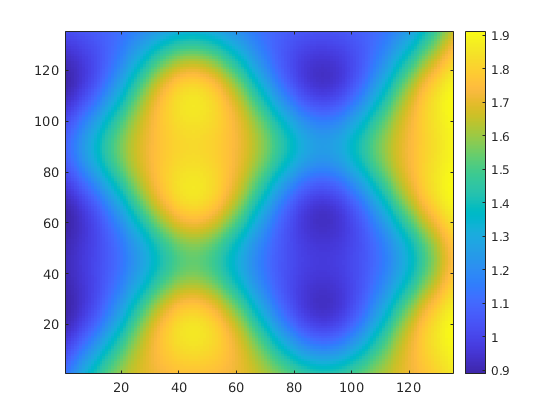

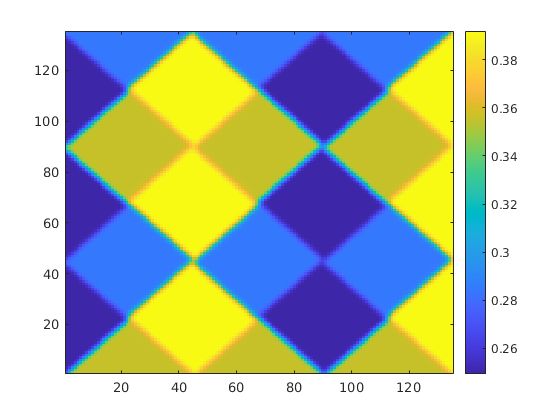

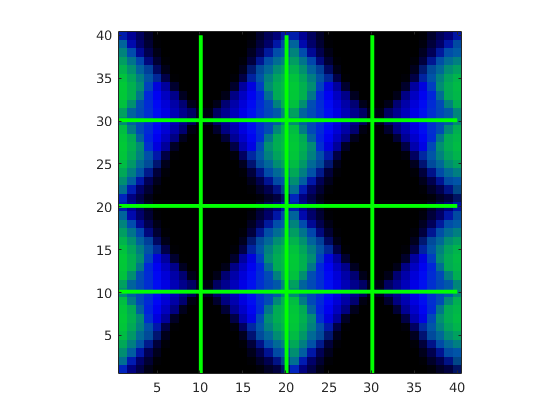

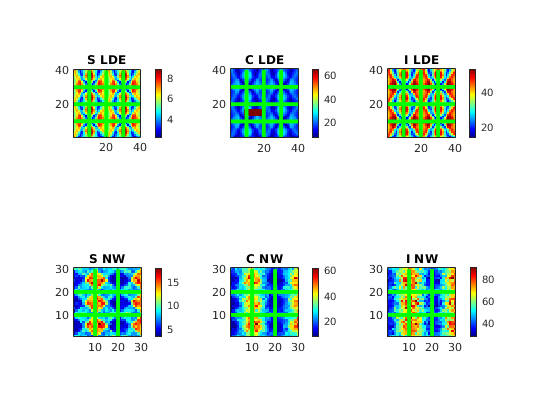

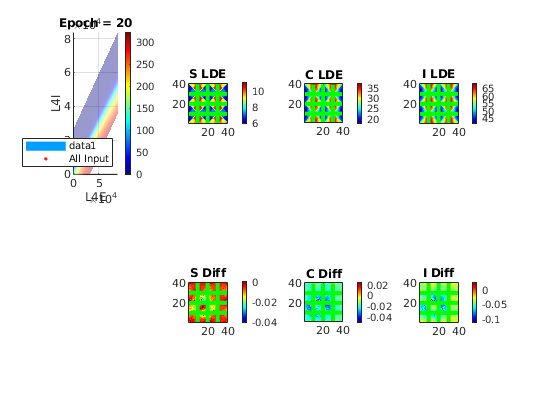

% figure('Name','epoch diff')
% subplot 231
% Ep1 = 15; Ep2 = 17; Ep3 = 20;
% ShowField(LDEEpoOut{Ep1}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep1, Ep3))
% subplot 232
% ShowField(LDEEpoOut{Ep1}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep1, Ep3))
% subplot 233
% ShowField(LDEEpoOut{Ep1}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep1, Ep3))
% 
% subplot 234
% ShowField(LDEEpoOut{Ep2}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep2, Ep3))
% subplot 235
% ShowField(LDEEpoOut{Ep2}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep2, Ep3))
% subplot 236
% ShowField(LDEEpoOut{Ep2}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep2, Ep3))

figure('Name','LDE Iteration')
subplot 241
LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,CtgrName,Ctgr,'S',true,false);
hold on
scatter(L4EUse,L4IUse,'r.','Displayname','All Input');
%     scatter(L4EUse(ORTPix),L4IUse(ORTPix),'r.','Displayname','ort');
%     scatter(L4EUse(OBLPix),L4IUse(OBLPix),'g.','Displayname','obl');
%     scatter(L4EUse(OPTPix),L4IUse(OPTPix),'b.','Displayname','opt');
%     scatter(L4EUse(ORTOBLBd_Pix),L4IUse(ORTOBLBd_Pix),'gd','Displayname','bd1');
%     scatter(L4EUse(OPTOBLBd_Pix),L4IUse(OPTOBLBd_Pix),'bx','Displayname','bd2');
legend('Location','southeast')
title(sprintf('Epoch = %d', Epc))
hold off
subplot 242
ShowField(LDEOut.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
subplot 243
ShowField(LDEOut.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
subplot 244
ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
subplot 246
ShowField(LDEEpoOut{Epc+1}.S - LDEEpoOut{Epc}.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S Diff')
subplot 247
ShowField(LDEEpoOut{Epc+1}.C - LDEEpoOut{Epc}.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C Diff')
subplot 248
ShowField(LDEEpoOut{Epc+1}.I - LDEEpoOut{Epc}.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I Diff')
drawnow

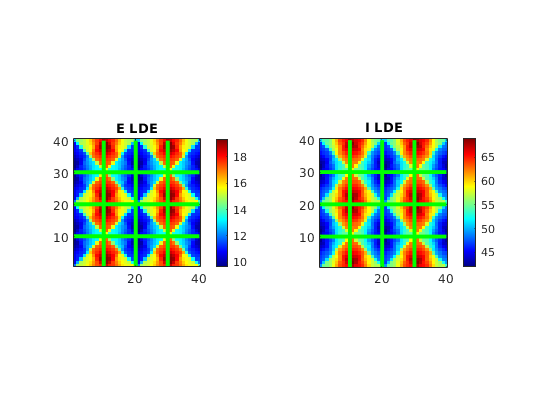

pause(0.5)

figure('Name','EImap')
subplot 121
ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,...
    1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'E LDE')
subplot 122
ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')

 Compute Frs

% LDENames = fieldnames(LDEOut)
% for Nid = 1:length(LDENames)
%     CurrField = LDEOut.(LDENames{Nid});
%     CurrMap = reshape(CurrField,N_HCOut*NPixX,N_HCOut*NPixY);
%     CurrMapShrk = CurrMap(1:N_HC*NPixY,1:N_HC*NPixX);
%     LDEOutShrk.(LDENames{Nid}) = reshape(CurrMapShrk,N_HC*NPixY*N_HC*NPixX,1);
%     MeanFrCtry(LDEOutShrk.(LDENames{Nid}))
% end

## 3.1 A systematic iteration comparison for different ini conditions.

MeanFrCtry = @(x1) [mean(x1(ORTPix)),mean(x1(OBLPix)),mean(x1(OPTPix))];

LDEIniAll = cell(10,1);
LDEEpoOutAll = cell(10,1);
L1DiffNormAll = cell(10,1);
IniDespt = cell(10,1);
p = 0.2; Epoc = 30;

10 Inis. 1: Bgd

IniDespt{1} = 'Bgd';
LDEIniAll{1}.S = ones(size(PixInptCtgr,1),1) * 2.47;
LDEIniAll{1}.C = ones(size(PixInptCtgr,1),1)  * 5.19;
LDEIniAll{1}.I = ones(size(PixInptCtgr,1),1)  * 14.36;

10 Inis. 2: Over excitation 70% above

IniDespt{2} = 'Over excitation 70%';
LDEIniAll{2}.S = PixInptCtgr * MeanFrCtry(FrSPixVec)'*1.7;
LDEIniAll{2}.C = PixInptCtgr * MeanFrCtry(FrCPixVec)'*1.7;
LDEIniAll{2}.I = PixInptCtgr * MeanFrCtry(FrIPixVec)'*1.7;

10 Inis. 3: Horizontal Grating

IniDespt{3} = 'Horizontal Grating';
PixInptCtgrHorz = zeros(size(PixInptCtgr));
for Col = 1:3
    PixInptCtgrHorz(:,Col) = reshape(reshape(PixInptCtgr(:,Col),30,30)',900,1);
end

LDEIniAll{3}.S = PixInptCtgrHorz * MeanFrCtry(FrSPixVec)';
LDEIniAll{3}.C = PixInptCtgrHorz * MeanFrCtry(FrCPixVec)';
LDEIniAll{3}.I = PixInptCtgrHorz * MeanFrCtry(FrIPixVec)';

10 Inis. 4: Obl grating 

IniDespt{4} = 'Obl grating';
MeanFrCtry1 = @(x1) [mean(x1(OPTPix)),mean(x1(OBLPix)),mean(x1(ORTPix))];
LDEIniAll{4}.S = PixInptCtgr * MeanFrCtry1(FrSPixVec)';
LDEIniAll{4}.C = PixInptCtgr * MeanFrCtry1(FrCPixVec)';
LDEIniAll{4}.I = PixInptCtgr * MeanFrCtry1(FrIPixVec)';

10 Inis. 5: Random Noise

IniDespt{5} = 'Random Noise';
Perc = 0.6;
RandomPert = rand(size(PixInptCtgr,1),1)*2*Perc+(1-Perc);
LDEIniAll{5}.S = PixInptCtgr * MeanFrCtry(FrSPixVec)'.*RandomPert;
LDEIniAll{5}.C = PixInptCtgr * MeanFrCtry(FrCPixVec)'.*RandomPert;
LDEIniAll{5}.I = PixInptCtgr * MeanFrCtry(FrIPixVec)'.*RandomPert;

10 Inis. 6: Repeat 2, elevating S,C by 2/3 and depressing I by 2/3

EPlus = 1.2; IMinus = 0.8;
IniDespt{6} = 'Repeat 2, E+ 2/3, I- 2/3';
LDEIniAll{6}.S = LDEIniAll{2}.S * EPlus;
LDEIniAll{6}.C = LDEIniAll{2}.C * EPlus;
LDEIniAll{6}.I = LDEIniAll{2}.I * IMinus;

10 Inis. 7: Repeat 3, elevating S,C by 2/3 and depressing I by 2/3

IniDespt{7} = 'Repeat 3, E+ 2/3, I- 2/3';
LDEIniAll{7}.S = LDEIniAll{3}.S * EPlus;
LDEIniAll{7}.C = LDEIniAll{3}.C * EPlus;
LDEIniAll{7}.I = LDEIniAll{3}.I * IMinus;

10 Inis. 8: Repeat 5, elevating S,C by 2/3 and depressing I by 2/3

IniDespt{8} = 'Repeat 5, E+ 2/3, I- 2/3';
LDEIniAll{8}.S = LDEIniAll{5}.S * EPlus;
LDEIniAll{8}.C = LDEIniAll{5}.C * EPlus;
LDEIniAll{8}.I = LDEIniAll{5}.I * IMinus;

10 Inis. 9: Repeat 1, elevating S,C by 2/3 and depressing I by 2/3

IniDespt{9} = 'Repeat 1, E+ 2/3, I- 2/3';
LDEIniAll{9}.S = LDEIniAll{1}.S * EPlus;
LDEIniAll{9}.C = LDEIniAll{1}.C * EPlus;
LDEIniAll{9}.I = LDEIniAll{1}.I * IMinus;

10 Inis. 10: Repeat 5, but start from *uniform fr* = network opt values everywhere.

IniDespt{10} = 'Random Noise from uniform';
MeanFrCtry2 = @(x1) [mean(x1(OPTPix)),mean(x1(OPTPix)),mean(x1(OPTPix))];
RandomPert2 = rand(size(PixInptCtgr,1),1)*1.2+0.4;
LDEIniAll{10}.S = PixInptCtgr * MeanFrCtry2(FrSPixVec)'.*RandomPert2;
LDEIniAll{10}.C = PixInptCtgr * MeanFrCtry2(FrCPixVec)'.*RandomPert2;
LDEIniAll{10}.I = PixInptCtgr * MeanFrCtry2(FrIPixVec)'.*RandomPert2;


Iterate for 30 times for all 10 initial conditions

figure('Name','10 initial conditions')
for IniInd = 1:length(LDEIniAll)
    [LDEEpoOutAll{IniInd},L1DiffNormAll{IniInd}] = ...
    LDEIterationMain(...
    PixInptCtgr,LDEIniAll{IniInd},p,Epoc,...
    C_SS_mean,C_CS_mean,C_IS_mean,...
    C_SC_mean,C_CC_mean,C_IC_mean,...
    C_SI_mean,C_CI_mean,C_II_mean,...
    L4EmeshX,L4ImeshY,LDEFrfunc)  ;
    
    subplot(5,2,IniInd)
    plot(L1DiffNormAll{IniInd})
    title(IniDespt{IniInd})
end

Comb = nchoosek(1:10,2);
L1DiffAll = zeros(size(Comb,1),1);
for CInd = 1:size(Comb,1)
    Ind1 = Comb(CInd,1); Ind2 = Comb(CInd,2);
    L1DiffAll(CInd) = ...
        mean(abs(LDEEpoOutAll{Ind1}{31}.I-LDEEpoOutAll{Ind2}{31}.I),'all') + ...
        mean(abs(LDEEpoOutAll{Ind1}{31}.S-LDEEpoOutAll{Ind2}{31}.S),'all') + ...
        mean(abs(LDEEpoOutAll{Ind1}{31}.C-LDEEpoOutAll{Ind2}{31}.C),'all');
end

% for ii = 1:10
%     subplot(2,5,ii)
%     ShowField(LDEEpoOutAll{10}{3*(ii-1)+1}.I ,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I Diff')
%     title(num2str(3*(ii-1)+1))
% end

## 4. Comparison between MF+V and LIF-only

L4lifSE = C_SS_Pixel_Us*FrSPixVec + C_SC_Pixel_Us*FrCPixVec;
L4lifSI = C_SI_Pixel_Us*FrIPixVec ;
L4lifCE = C_CS_Pixel_Us*FrSPixVec + C_CC_Pixel_Us*FrCPixVec;
L4lifCI = C_CI_Pixel_Us*FrIPixVec ;
L4lifIE = C_IS_Pixel_Us*FrSPixVec + C_IC_Pixel_Us*FrCPixVec;
L4lifII = C_II_Pixel_Us*FrIPixVec ;
L4localSE = diag(C_SS_Pixel_Us).*FrSPixVec + diag(C_SC_Pixel_Us).*FrCPixVec;
L4localSI = diag(C_SI_Pixel_Us).*FrIPixVec ;
L4localCE = diag(C_CS_Pixel_Us).*FrSPixVec + diag(C_CC_Pixel_Us).*FrCPixVec;
L4localCI = diag(C_CI_Pixel_Us).*FrIPixVec ;
L4localIE = diag(C_IS_Pixel_Us).*FrSPixVec + diag(C_IC_Pixel_Us).*FrCPixVec;
L4localII = diag(C_II_Pixel_Us).*FrIPixVec ;
L4EmfvUse = C_SS_Pixel_Us*FrSPixVec +... - diag(C_SS_Pixel_Us).*FrSPixVec + ...
            C_CS_Pixel_Us*FrSPixVec +... - diag(C_CS_Pixel_Us).*FrSPixVec + ...
            C_IS_Pixel_Us*FrSPixVec +... - diag(C_IS_Pixel_Us).*FrSPixVec + ...
            C_SC_Pixel_Us*FrCPixVec +... - diag(C_SC_Pixel_Us).*FrCPixVec + ...
            C_CC_Pixel_Us*FrCPixVec +... - diag(C_CC_Pixel_Us).*FrCPixVec + ...
            C_IC_Pixel_Us*FrCPixVec ;% - diag(C_IC_Pixel_Us).*FrCPixVec ;
L4ImfvUse = C_SI_Pixel_Us*FrIPixVec +... - diag(C_SI_Pixel_Us).*FrIPixVec + ...
            C_CI_Pixel_Us*FrIPixVec +... - diag(C_CI_Pixel_Us).*FrIPixVec + ...
            C_II_Pixel_Us*FrIPixVec ;% - diag(C_II_Pixel_Us).*FrIPixVec ;

Now consider a pixel containing 3 neurons: S C I

Pick up 10 pixels

%InputCtgrList = [1,1, 1,  2,  2,  2,   3,  3,   3];
%PixRow = [5,5,25,  1,10,20,  5,15,5 ];
PixRow = randi([1,30],50,1);
%PixCol = [1,20,20, 15,15,26, 10,10,29];
PixCol = randi([1,30],50,1);
PixIndList = (PixCol-1)*N_HC*NPixY +  PixRow ;% [7,55,615,180,450,645, 565,326, 276];
VRcdAll = cell(size(PixIndList));
SpRcdAll = cell(size(PixIndList));
FrRcdAve = zeros(length(PixIndList),3);

for LIFtestInd = 1:length(PixIndList)
%InputCtgr = InputCtgrList(LIFtestInd); 
PixInd = PixIndList(LIFtestInd); % pixel and input category

FL6_One = unique(L6Ord_F)/1e3;
rL6SU = L6S_Pixel(PixInd);
rL6CU = L6C_Pixel(PixInd);
rL6IU = L6I_Pixel(PixInd);
L4SE = L4lifSE(PixInd)/1e3*(1-p_EEFail); L4CE = L4lifCE(PixInd)/1e3*(1-p_EEFail); L4IE = L4lifIE(PixInd)/1e3;
L4SI = L4lifSI(PixInd)/1e3;              L4CI = L4lifCI(PixInd)/1e3;              L4II = L4lifII(PixInd)/1e3;

LIFSimuT = 50*1e3; TimeFrac = 1/(LIFSimuT/1e3)/LGNFreq;
lgn_Events    = PoissonInputForNetwork(3, 45*[N_Slgn;N_Clgn;N_Ilgn]/1e3 ,LIFSimuT*TimeFrac,dt,true);
AmbPix_Events = PoissonInputForNetwork(3,[rS_amb;rC_amb;rI_amb],LIFSimuT*TimeFrac,dt,true);
L6Pix_Events  = PoissonInputForNetwork(3,[rL6SU; rL6CU; rL6IU], LIFSimuT*TimeFrac,dt,true);
L4Pix_EventsE = PoissonInputForNetwork(3,[L4SE; L4CE; L4IE],LIFSimuT*TimeFrac,dt,true);
L4Pix_EventsI = PoissonInputForNetwork(3,[L4SI; L4CI; L4II],LIFSimuT*TimeFrac,dt,true);
gL = [gL_E*ones(2,1); gL_I*ones(1)];

Can precompute all Gs...

% Now adjust lgn to S
lgn_SOnOff = [0.045, 0.0675, 0.09;
              0.045, 0.0225, 0.00];
lgn_Slif = [lambda_SOn_Pixel';lambda_SOff_Pixel'];
lgn_Slifort = mean(mean(lgn_Slif))*ones(2,1);

lgnAdj = lgn_Slif(:,PixInd)./lgn_Slifort;
lgnAdjU = reshape(repmat(lgnAdj,1,floor(size(L4Pix_EventsE,2)/2))', 1, 2*floor(size(L4Pix_EventsE,2)/2));

Disp some # of spikes

% sprintf('#L6 = %.4f', sum(FL6_One.*PixL6Ctgr(PixInd,:)))
% sprintf('#L4SE total = %.4f, #L4SI total = %.4f',L4lifSE(PixInd)/1e3,L4lifSI(PixInd)/1e3)
% sprintf('#L4CE total = %.4f, #L4CI total = %.4f',L4lifCE(PixInd)/1e3,L4lifCI(PixInd)/1e3)
% sprintf('#L4IE total = %.4f, #L4II total = %.4f',L4lifIE(PixInd)/1e3,L4lifII(PixInd)/1e3)
% sprintf('#L4SE local = %.4f, #L4SI local = %.4f',L4localSE(PixInd)/1e3,L4localSI(PixInd)/1e3)
% sprintf('#L4CE local = %.4f, #L4CI local = %.4f',L4localCE(PixInd)/1e3,L4localCI(PixInd)/1e3)
% sprintf('#L4IE local = %.4f, #L4II local = %.4f',L4localIE(PixInd)/1e3,L4localII(PixInd)/1e3)

For each cycle, initiate a new start

TCyc = floor(1/TimeFrac);
VRcdCyc = cell(TCyc,1);
SpRcdCyc = cell(TCyc,1);

RefTimer = zeros(3, 1); % initiate the timer of ref
vt = zeros(3, 1); 
tic
for TInt = 1:TCyc
    VRcd = zeros(size(L4Pix_EventsE));
    SpLIF = zeros(3, 1);

    % New Gs
    lgnPix_Events = lgn_Events(:,randperm(size(lgn_Events,2)));
    lgnPix_Events(1,1:length(lgnAdjU)) = lgnPix_Events(1,1:length(lgnAdjU)).*lgnAdjU;

    winAMPA = 0:dt:tau_ampa_D*3;
    winNMDA = 0:dt:tau_nmda_D*3;
    winGABA = 0:dt:tau_gaba_D*3;
    KerAMPA = 1/(tau_ampa_D-tau_ampa_R) * (exp(-winAMPA/tau_ampa_D) - exp(-winAMPA/tau_ampa_R));
    KerNMDA = 1/(tau_nmda_D-tau_nmda_R) * (exp(-winNMDA/tau_nmda_D) - exp(-winNMDA/tau_nmda_R));
    KerGABA = 1/(tau_gaba_D-tau_gaba_R) * (exp(-winGABA/tau_gaba_D) - exp(-winGABA/tau_gaba_R));
    KerAMPA = KerAMPA / (sum(KerAMPA)*dt);
    KerNMDA = KerNMDA / (sum(KerNMDA)*dt);
    KerGABA = KerGABA / (sum(KerGABA)*dt);
    % Incorporate L4 and other input
    ampaInp = single(...
          [S_Elgn * lgnPix_Events(1:2,:);            S_Ilgn * lgnPix_Events(3,:)]...
        +  S_amb * AmbPix_Events ... % S_amb identical for E and I
        + [S_EL6 * L6Pix_Events(1:2,:) * rhoE_ampa;  S_IL6 * L6Pix_Events(3,:) * rhoI_ampa]...
        + [S_EE  * L4Pix_EventsE(1:2,:) * rhoE_ampa; S_IE * L4Pix_EventsE(3,:) * rhoI_ampa]);
    nmdaInp = single(...
          [S_EL6 * L6Pix_Events(1:2,:) * rhoE_nmda;  S_IL6 * L6Pix_Events(3,:) * rhoI_nmda]...
        + [S_EE  * L4Pix_EventsE(1:2,:) * rhoE_nmda; S_IE * L4Pix_EventsE(3,:) * rhoI_nmda]);
    gabaInp = single(...
          [S_EI * L4Pix_EventsI(1:2,:);              S_II * L4Pix_EventsI(3,:)] );
    %% Precompute All Conductances: Speed up by ifft/fft
    n = size(ampaInp,2);
    GAMPA = ifft(fft(ampaInp',n) .* repmat(fft(KerAMPA',n),1,3))';
    GNMDA = ifft(fft(nmdaInp',n) .* repmat(fft(KerNMDA',n),1,3))';
    GGABA = ifft(fft(gabaInp',n) .* repmat(fft(KerGABA',n),1,3))';

    GE = GAMPA + GNMDA;  GI = GGABA;
    
    for tInd = 1:size(L4Pix_EventsE,2)
        % Firstly, refrectory neurons get out if timer reachs t_ref
        RefTimer(isnan(vt)) = RefTimer(isnan(vt)) + dt;
        vt(RefTimer>=tau_ref) = 0;
        RefTimer(RefTimer>=tau_ref) = 0;

        ov  = vt + dt*(-gL.*vt - GE(:,tInd).*(vt-Ve) - GI(:,tInd).*(vt-Vi));
        SpNow = single(ov>=1);
        ov(ov>=1) = nan;
        VRcd(:,tInd) = ov;
        % Compute meanV
            SpLIF = SpLIF + SpNow;
        % Transfer variables
        vt = ov;
    end
    VRcdCyc{TInt} = VRcd;
    SpRcdCyc{TInt} = SpLIF;
end
toc
VRcdAll{LIFtestInd} = VRcdCyc;
SpRcdAll{LIFtestInd} = SpRcdCyc;
SpRcdMat = cell2mat(SpRcdCyc')';
FrRcdAve(LIFtestInd,:) = mean(SpRcdMat(10:end,:))*LGNFreq; % The actual firing rates
%LDEresults = zeros(length(FrSPixVec),3);
end

Now for LDE results

DirLDEresults(:,1) = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.S.ORT,LDEFrfunc.S.OBL,LDEFrfunc.S.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.S,...
    PixInptCtgr);
%ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
DirLDEresults(:,2)  = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.C.ORT,LDEFrfunc.C.OBL,LDEFrfunc.C.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.C,...
    PixInptCtgr);
% ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
DirLDEresults(:,3)  = ...
    LDEIterFunc(L4EmeshX, L4ImeshY,...
    LDEFrfunc.I.ORT,LDEFrfunc.I.OBL,LDEFrfunc.I.OPT,...
    L4EmfvUse,L4ImfvUse,LDEUse.I,...
    PixInptCtgr);

FrLDEDir = DirLDEresults(PixIndList,:);

FrNW = [FrSPixVec(PixIndList),FrCPixVec(PixIndList),FrIPixVec(PixIndList)];

figure('Name','LIF-only results')
subplot 231
scatter(FrRcdAve(1:50,1),FrNW(:,1))
hold on
plot(1:100,1:100)
xlabel('LIF-only:S'); ylabel('NW:S')
axis([0 20 0 20]); axis square
subplot 232
scatter(FrRcdAve(1:50,2),FrNW(:,2))
hold on
plot(1:100,1:100)
xlabel('LIF-only:C'); ylabel('NW:C')
axis([0 60 0 60]); axis square

subplot 233
scatter(FrRcdAve(1:50,3),FrNW(:,3))
hold on
plot(1:100,1:100)
xlabel('LIF-only:I'); ylabel('NW:I')
axis([30 100 30 100]); axis square

subplot 234
scatter(FrLDEDir(1:50,1),FrNW(:,1))
hold on
plot(1:100,1:100)
xlabel('LIF-LDE:S'); ylabel('NW:S')
axis([0 20 0 20]); axis square
subplot 235
scatter(FrLDEDir(1:50,2),FrNW(:,2))
hold on
plot(1:100,1:100)
xlabel('LIF-LDE:C'); ylabel('NW:C')
axis([0 60 0 60]); axis square

subplot 236
scatter(FrLDEDir(1:50,3),FrNW(:,3))
hold on
plot(1:100,1:100)
xlabel('LIF-LDE:I'); ylabel('NW:I')
axis([30 100 30 100]); axis square

A figure showing all the details

close all
TRcdSteps = 1/4:1/4:LIFSimuT/1e3;
DomName = {'ort','obl','opt'};
for PlotInd = 1:9
    SpRcdU = SpRcdAll{PlotInd};
    SpRcdU = cell2mat(SpRcdU');
    figure(1)
    % For each subplot
    subplot(3,3,PlotInd)
    hold on
    plot(TRcdSteps,SpRcdU(1,:)*LGNFreq,'r','DisplayName','S-LIF')
    plot(TRcdSteps,SpRcdU(2,:)*LGNFreq,'g','DisplayName','C-LIF')
    plot(TRcdSteps,SpRcdU(3,:)*LGNFreq,'b','DisplayName','I-LIF')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrSPixVec(PixIndList(PlotInd)),...
        'r--','DisplayName','S-NW')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrCPixVec(PixIndList(PlotInd)),...
        'g--','DisplayName','C-NW')
    plot(TRcdSteps,ones(size(TRcdSteps))*FrIPixVec(PixIndList(PlotInd)),...
        'b--','DisplayName','I-NW')
    xlabel('T (s)'); ylabel('Frs'); ylim([0 120])
    title(['OD:', DomName{InputCtgrList(PlotInd)}])
    if PlotInd == 1
        legend
    end
    
    L4EPixU = L4EmfvUse(PixIndList(PlotInd))
    L4IPixU = L4ImfvUse(PixIndList(PlotInd))
    LDEInd = find(abs(L4ERcrd-L4EPixU)+abs(L4IRcrd-L4IPixU) == min(abs(L4ERcrd-L4EPixU)+abs(L4IRcrd-L4IPixU),[],'all'))
    InputCtgrList(PlotInd)
    if InputCtgrList(PlotInd) == 3
        fMFV = fLDE_OPT{LDEInd};
    elseif InputCtgrList(PlotInd) == 2
        fMFV = fLDE_OBL{LDEInd};
        
    elseif InputCtgrList(PlotInd) == 1
        fMFV = fLDE_ORT{LDEInd};
        
    end
    
    fMFV(fMFV<0) = eps;
    figure(2)
    subplot(3,3,PlotInd)
    hold on
    plot((fMFV(1,:)+fMFV(3,:))/2,'r','Marker','o','DisplayName','S-MFV')
    plot((fMFV(2,:)+fMFV(4,:))/2,'g','Marker','o','DisplayName','C-MFV')
    plot(fMFV(5,:),'b','Marker','o','DisplayName','I-MFV')
    plot(1:60,ones(size(1:60))*FrSPixVec(PixIndList(PlotInd)),...
        'r--','DisplayName','S-NW')
    plot(1:60,ones(size(1:60))*FrCPixVec(PixIndList(PlotInd)),...
        'g--','DisplayName','C-NW')
    plot(1:60,ones(size(1:60))*FrIPixVec(PixIndList(PlotInd)),...
        'b--','DisplayName','I-NW')
    xlabel('epochs');ylim([0 120]);xlim([0 60])
    if PlotInd == 1
        legend
    end
end


